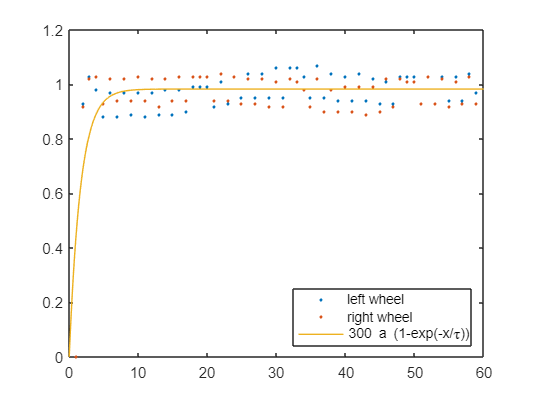

data = csvread('motorData.csv');
leftWheel = (data(:,1));
rightWheel = (data(:,2));
figure()
plot(leftWheel, '.')
hold on
plot(rightWheel,'.')
legend('left wheel', 'right wheel', location='southeast')

% Values from curvefitter
a = 0.003275;
tau = 1.642;

fplot(@(x) 300*a*(1-exp(-x/tau)))
ylim([0 1.2])
xlim([0,60])